% 加载数据
data = load("D:\tree\Machine Learning\CS229-code\ex2data2.txt");
X = data(:, [1, 2]); % 特征
y = data(:, 3); % 标签
data

data =     0.0513    0.6996    1.0000
   -0.0927    0.6849    1.0000
   -0.2137    0.6923    1.0000
   -0.3750    0.5022    1.0000
   -0.5132    0.4656    1.0000
   -0.5248    0.2098    1.0000
   -0.3980    0.0344    1.0000
   -0.3059   -0.1923    1.0000
    0.0167   -0.4042    1.0000
    0.1319   -0.5139    1.0000


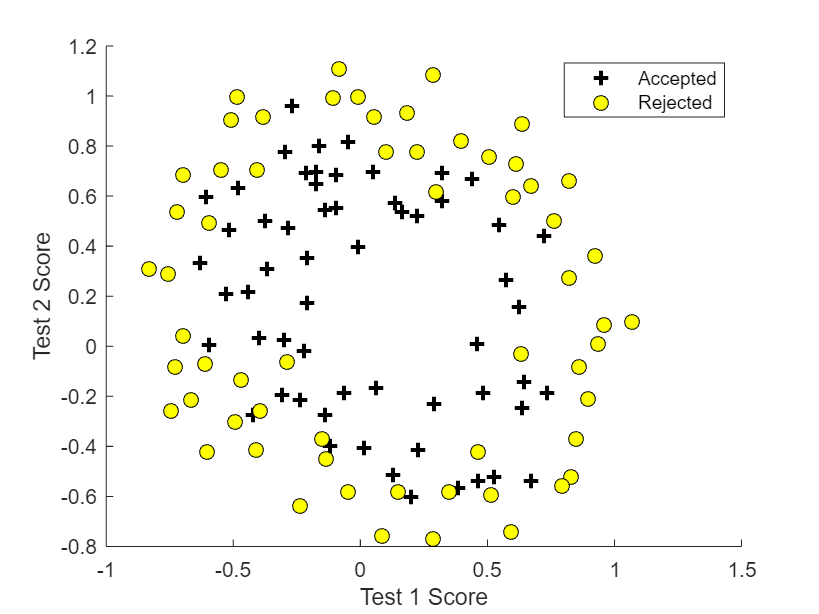


% 可视化数据
figure; hold on;

% 绘制正类和负类样本
pos = find(y == 1);
neg = find(y == 0);

plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);

xlabel('Test 1 Score');
ylabel('Test 2 Score');
legend('Accepted', 'Rejected');
hold off;

% 特征映射
degree = 6;
X_poly = mapFeature(X(:,1), X(:,2));
X_poly

X_poly =     1.0000    0.0513    0.6996    0.0026    0.0359    0.4894    0.0001    0.0018    0.0251    0.3424    0.0000    0.0001    0.0013    0.0176    0.2395    0.0000    0.0000    0.0001    0.0009    0.0123    0.1675    0.0000    0.0000    0.0000    0.0000    0.0006    0.0086    0.1172
    1.0000   -0.0927    0.6849    0.0086   -0.0635    0.4691   -0.0008    0.0059   -0.0435    0.3213    0.0001   -0.0005    0.0040   -0.0298    0.2201   -0.0000    0.0001   -0.0004    0.0028   -0.0204    0.1508    0.0000   -0.0000    0.0000   -0.0003    0.0019   -0.0140    0.1033
    1.0000   -0.2137    0.6923    0.0457   -0.1479    0.4792   -0.0098    0.0316   -0.1024    0.3317    0.0021   -0.0068    0.0219   -0.0709    0.2296   -0.0004    0.0014   -0.0047    0.0152   -0.0491    0.1590    0.0001   -0.0003    0.0010   -0.0032    0.0105   -0.0340    0.1100
    1.0000   -0.3750    0.5022    0.1406   -0.1883    0.2522   -0.0527    0.0706   -0.0946    0.1266    0.0198   -0.0265    0.0355   -0.0475    0.06

% 初始化参数
initial_theta = zeros(size(X_poly, 2), 1);
% 设置正则化参数
lambda = 1;

% 优化选项
options = optimset('GradObj', 'on', 'MaxIter', 400);
% 进行优化
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X_poly, y, lambda)), initial_theta, options);


找到局部最小值。

优化已完成，因为梯度大小小于
最优性容差的值。

<停止条件详细信息>


% 打印最终代价
fprintf('Final cost: %f\n', J);

Final cost: 0.529003


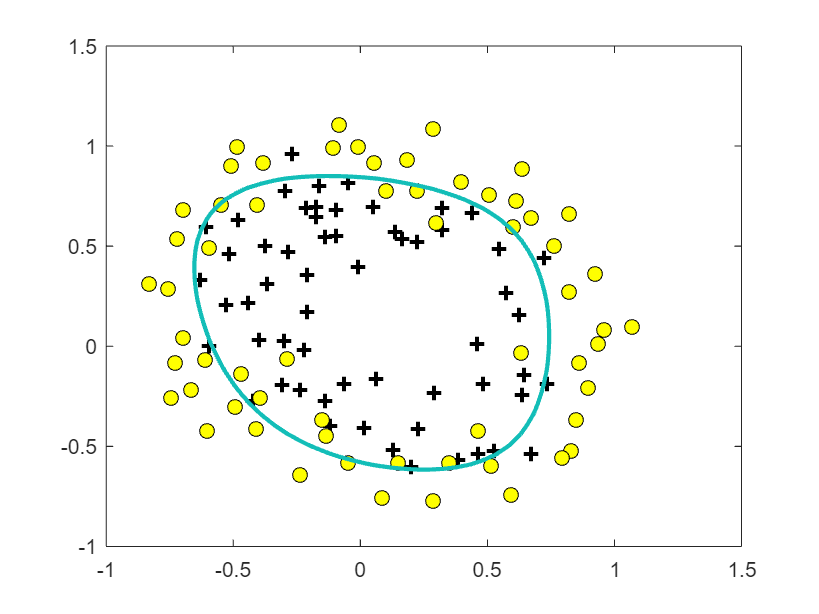

% 决策边界绘制
plotDecisionBoundary(theta, X_poly, y);

function plotData(X, y)
    % 找到正负类的索引
    pos = find(y == 1);
    neg = find(y == 0);

    % 绘制正类数据点
    plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, 'MarkerSize', 7);
    hold on;

    % 绘制负类数据点
    plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7);

    hold off;
end

function g = sigmoid(z)
    g = 1.0 ./ (1.0 + exp(-z));
end

function plotDecisionBoundary(theta, X, y)
    % 绘制数据点
    plotData(X(:,2:3), y);
    hold on

    if size(X, 2) <= 3
        % 只需要两个特征时，直接绘制线
        plot_x = [min(X(:,2))-2,  max(X(:,2))+2];

        plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));

        plot(plot_x, plot_y)
        
        legend('y = 1', 'y = 0', 'Decision Boundary')
        axis([30, 100, 30, 100])
    else
        % 多特征时，绘制等高线
        
        u = linspace(-1, 1.5, 50);
        v = linspace(-1, 1.5, 50);

        z = zeros(length(u), length(v));
        
        for i = 1:length(u)
            for j = 1:length(v)
                z(i,j) = mapFeature(u(i), v(j)) * theta;
            end
        end
        z = z'; % 转置z以符合contour的输入格式

        contour(u, v, z, [0, 0], 'LineWidth', 2)
    end
    
    hold off
end

function [J, grad] = costFunctionReg(theta, X, y, lambda)
    m = length(y); % 样本数量

    J = 0;
    grad = zeros(size(theta));

    h = sigmoid(X * theta);
    
    % 正则化代价函数
    J = (1/m) * (-y' * log(h) - (1 - y)' * log(1 - h)) + ...
        (lambda / (2*m)) * sum(theta(2:end).^2);

    % 正则化梯度
    grad(1) = (1/m) * X(:,1)' * (h - y);
    grad(2:end) = (1/m) * X(:,2:end)' * (h - y) + (lambda/m) * theta(2:end);
end

function out = mapFeature(X1, X2)
    degree = 6;
    out = ones(size(X1(:,1)));
    for i = 1:degree
        for j = 0:i
            out(:, end+1) = (X1.^(i-j)).*(X2.^j);
        end
    end
end
